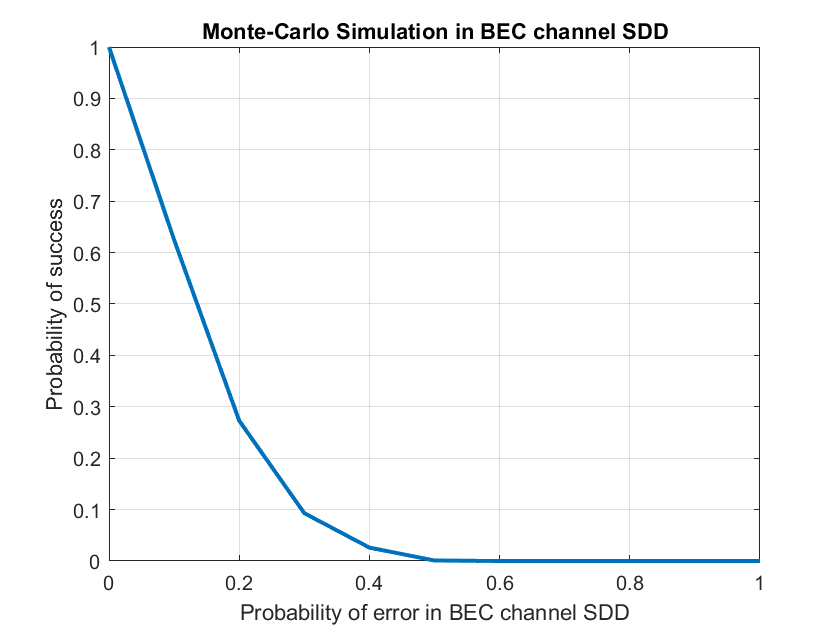

 load Hmatrix3.mat

h=H;
row=height(h);
colm=length(h);
transmitted=zeros(1,length(h));  %Input of BSC Channel 
p=0:0.1:1;
Nsim=1000;
nsuc=zeros(1,length(p));  %Array to store success

for yy=1:length(p)
    
    for z=1:Nsim %Monte-Carlo Simulation
         
        noise=rand(1,colm)<p(yy);   %noise generated
        Msg_received=rem(transmitted+noise,2); %message generated after introducing noise

        for a=1:100 % Iteration loop
            %majority voting array for storing votes of respective bits
            %variable node sending its own value and storing it 
            no_0=rem(Msg_received+1,2); %storing its own voting for bit 0
            no_1=Msg_received; %Storing its own voting for bit 1
            temp=Msg_received; %message stored in temporary variable used for breaking condition later in this code 
            
            for i=1:row
                for j=1:colm
                    if(h(i,j)==1)
                        s=0;
                        for k=1:colm
                            %check node sending values to variable node by taking XOR of all connected bits except the given bit            
                            if(h(i,k)==1 && k~=j)
                                s=s+Msg_received(k);
                            end
                        end
                        
                        s=rem(s,2);%here doing modulo 2 which is equivalent to XOR of that variable
                        %incrementing majority voting array according to value received by check node                      
                        if(s==1)
                            no_1(j)=no_1(j)+1;
                        else
                            no_0(j)=no_0(j)+1;
                        end
                    end
                end
            end 
            
            %doing majority Voting
            for l=1:j     
                if(no_1(l)>no_0(l)) 
                    Msg_received(l)=1;
                elseif(no_0(l)>no_1(l))
                    Msg_received(l)=0;
                end             
            end
            
            if(sum(Msg_received)==0) %checking if messsage is successfully decoded or not and breaking the iteration loop
                nsuc(yy)=nsuc(yy)+1;
                break;
            end
            if(temp==Msg_received) %breaking condition when code cant be decoded successfully
                 break;
            end
        end
    end
end

pp=nsuc/Nsim; %calculating success probability
plot(p,pp,'LineWidth',2); %plotting the graph
title("Monte-Carlo Simulation in BSC channel HDD");
xlabel("Probability of error in BSC channel HDD");ylabel("Probability of success"); grid on;